# 1.2 数字信号处理过程：模拟信号 → 采样 → 量化 → 数字处理 → D/A → 平滑

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。 课堂上不讲公式，只看四幅图；公式只出现在末尾的核验里。 图和核验数据写入同目录 results。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');   % 由 build_mlx 设置：Live Script 里每格单独一张图，便于阅读；普通运行时拼成一张图存 PNG
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end   % 图例：Live 模式放图下方不压数据；拼图模式自动避让
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：一路“模拟信号”与它的采样

想要的成分：2 Hz；混进来的干扰：15 Hz。采样率 100 Hz，采 2 秒。

fs = 100; T = 1/fs; dur = 2;
xa = @(t) sin(2*pi*2*t) + 0.5*sin(2*pi*15*t);   % 教材图 1.2.1 里的 x_a(t)
tc = 0:1e-4:dur;                                 % 很密的时间网格，代表“连续”
n = 0:dur*fs; t = n*T;                           % 采样时刻 t = nT
x = xa(t);                                       % 采样：离散时间、连续幅值

## 演示2：量化——幅值也变成有限个数码

full = 2;                                        % 量化范围 ±2（信号峰值 1.5，不削顶）
quantize = @(v, bits) max(-full, min(full - 2*full/2^bits, round(v/(2*full)*2^bits)/2^bits*2*full));
x3 = quantize(x, 3);                             % 3 位：8 个电平，误差明显
x8 = quantize(x, 8);                             % 8 位：256 个电平
step3 = 2*full/2^3; step8 = 2*full/2^8;

## 演示3：数字处理——把相邻 5 个数取平均（这就是一个“系统”）

M = 5; b = ones(1, M)/M;
y = filter(b, 1, x8);                            % 输入 8 位数字信号，输出数字信号

## 演示4：D/A 变换——零阶保持，再平滑

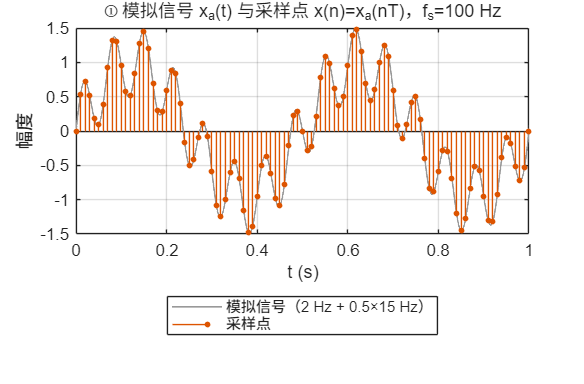

tzoh = tc; yzoh = interp1(t, y, tc, 'previous', 'extrap');   % 零阶保持：每个样本保持一个采样周期
smoothLen = round(0.02/1e-4);                    % 平滑滤波：20 ms 窗的滑动平均（近似模拟平滑滤波器）
ysmooth = filter(ones(1, smoothLen)/smoothLen, 1, yzoh);

if ~LIVE, f1 = figure('Name','01 数字信号处理过程','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(tc, xa(tc), 'Color', [0.6 0.6 0.6], 'LineWidth', 1); hold on;
stem(t, x, 'filled', 'MarkerSize', 3); grid on; xlim([0 1]);
title('① 模拟信号 x_a(t) 与采样点 x(n)=x_a(nT)，f_s=100 Hz'); xlabel('t (s)'); ylabel('幅度');
legend('模拟信号（2 Hz + 0.5×15 Hz）','采样点');

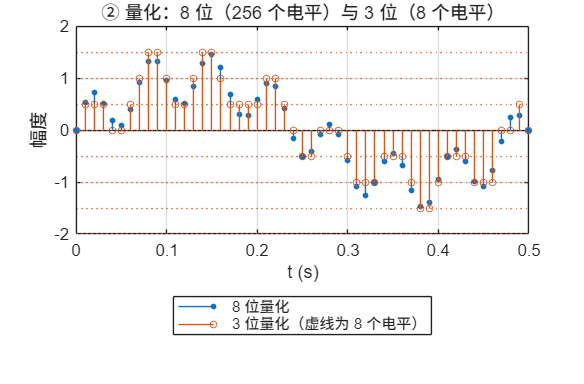

newpanel(); stem(t, x8, 'filled', 'MarkerSize', 3); hold on;
stem(t, x3, 'MarkerSize', 4, 'Color', [0.85 0.33 0.1]); grid on; xlim([0 0.5]);
yline((-4:3)*step3, ':', 'Color', [0.85 0.33 0.1 0.5]);
title(sprintf('② 量化：8 位（%d 个电平）与 3 位（%d 个电平）', 2^8, 2^3)); xlabel('t (s)'); ylabel('幅度');
legend('8 位量化','3 位量化（虚线为 8 个电平）');

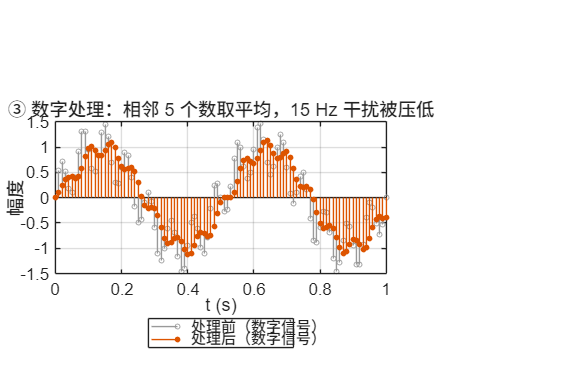

newpanel(); stem(t, x8, 'MarkerSize', 3, 'Color', [0.6 0.6 0.6]); hold on;
stem(t, y, 'filled', 'MarkerSize', 3); grid on; xlim([0 1]);
title('③ 数字处理：相邻 5 个数取平均，15 Hz 干扰被压低'); xlabel('t (s)'); ylabel('幅度');
legend('处理前（数字信号）','处理后（数字信号）');

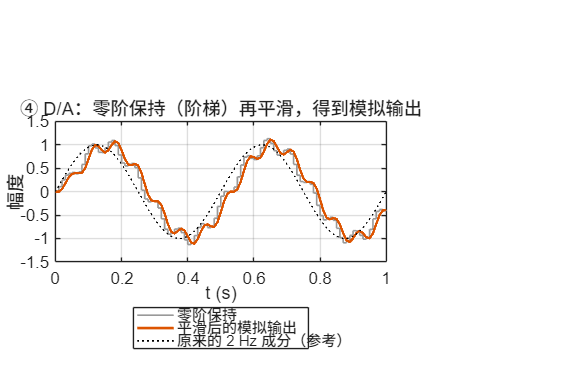

newpanel(); stairs(tzoh, yzoh, 'Color', [0.6 0.6 0.6], 'LineWidth', 1); hold on;
plot(tc, ysmooth, 'LineWidth', 1.6); plot(tc, sin(2*pi*2*tc), 'k:', 'LineWidth', 1); grid on; xlim([0 1]);
title('④ D/A：零阶保持（阶梯）再平滑，得到模拟输出'); xlabel('t (s)'); ylabel('幅度');
legend('零阶保持','平滑后的模拟输出','原来的 2 Hz 成分（参考）');

if ~LIVE, sgtitle('教材图 1.2.1 的四步：预处理与采样 → A/D 量化 → 数字处理 → D/A 与平滑'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-dsp-chain.png'), 'Resolution', 150); end

## 教师核验：量化误差界、滑动平均对两个频率的增益

qerr3 = max(abs(x - x3)); qerr8 = max(abs(x - x8));
assert(qerr3 <= step3/2 + 1e-12 && qerr8 <= step8/2 + 1e-12, '量化误差超过半个台阶');
gain = @(f) abs(sin(M*pi*f/fs) / (M*sin(pi*f/fs)));   % 5 点平均的幅频响应（第 2 章内容，这里只作核验）
% 在稳态段用最小二乘拟合 2 Hz 与 15 Hz 分量的幅值
idx = n >= M-1; tt = t(idx);
A = [sin(2*pi*2*tt)', cos(2*pi*2*tt)', sin(2*pi*15*tt)', cos(2*pi*15*tt)', ones(numel(tt),1)];
c = A \ y(idx)';
amp2 = hypot(c(1), c(2)); amp15 = hypot(c(3), c(4));
assert(abs(amp2 - 1.0*gain(2)) < 0.02 && abs(amp15 - 0.5*gain(15)) < 0.02, '滑动平均增益与拟合幅值不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'fs', fs, 'duration_s', dur, 'signal', '2 Hz (amp 1) + 15 Hz (amp 0.5)', ...
    'quant_step_3bit', step3, 'quant_step_8bit', step8, 'quant_err_max_3bit', qerr3, 'quant_err_max_8bit', qerr8, ...
    'moving_average_taps', M, 'gain_2Hz_formula', gain(2), 'gain_15Hz_formula', gain(15), ...
    'amp_2Hz_fitted', amp2, 'amp_15Hz_fitted', amp15, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification.json'), 'w', 'n', 'UTF-8');
assert(fid >= 0, '无法创建核验记录');
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics);

         matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                 run_at: '2026-09-18 18:40:08'
                     fs: 100
             duration_s: 2
                 signal: '2 Hz (amp 1) + 15 Hz (amp 0.5)'
        quant_step_3bit: 0.5000
        quant_step_8bit: 0.0156
     quant_err_max_3bit: 0.2460
     quant_err_max_8bit: 0.0075
    moving_average_taps: 5
       gain_2Hz_formula: 0.9843
      gain_15Hz_formula: 0.3115
         amp_2Hz_fitted: 0.9855
        amp_15Hz_fitted: 0.1561
      all_checks_passed: 1



fprintf('\n课堂图已保存到：%s\n', outdir);


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList)
    axesList(a).Toolbar.Visible = 'off';
end
drawnow;
end